# Intro

% This main script will outline the story for our animation. It will
% implement various transformation functions in loops to animate a character.

% Each of us will be responsible for one of these scenes. Once we figure out a 
% story, we should include the expected inputs and outputs.

## Animation

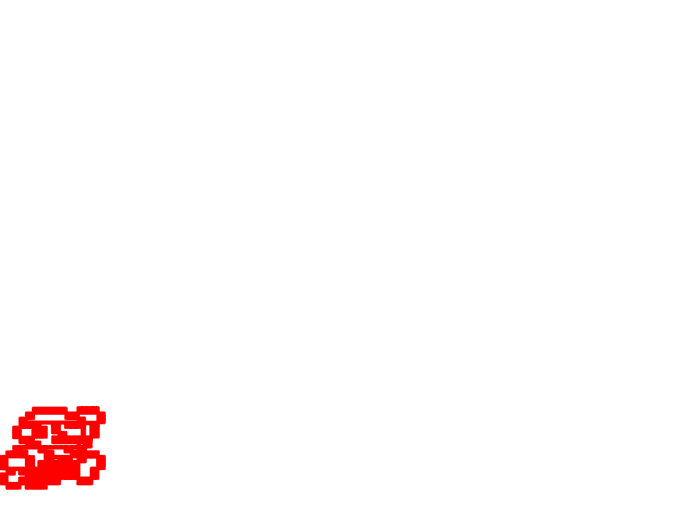

% SCENE 1 
% (Panning Camera) Large background, smaller view follows mario
% Background:SunnyMarioLevel.jpg
% est Duation:28 seconds 

clf

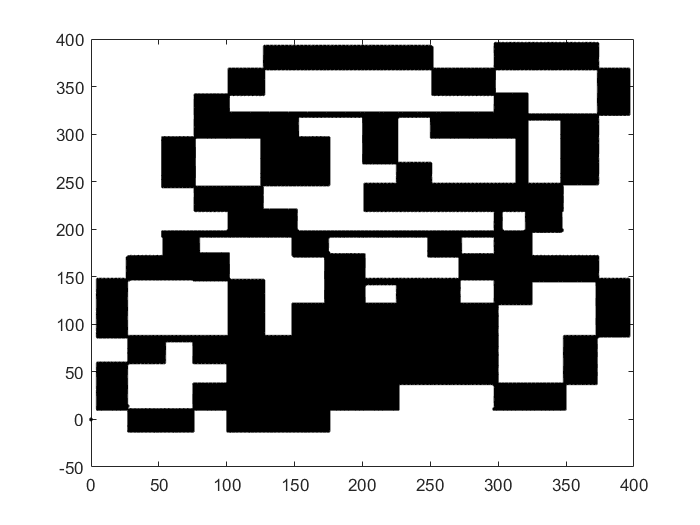

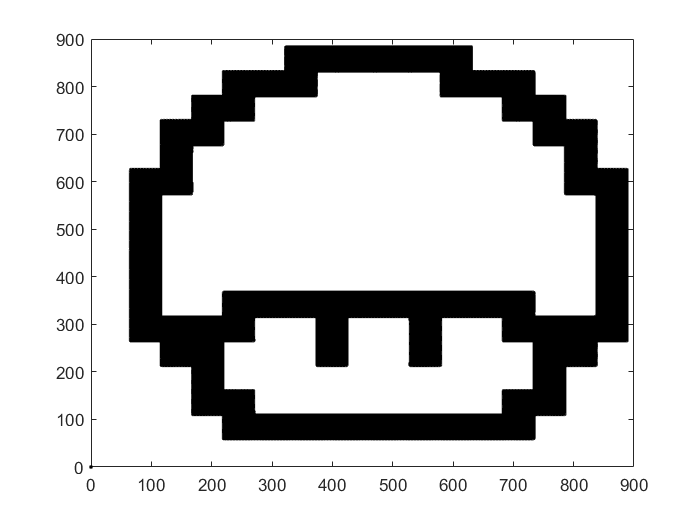

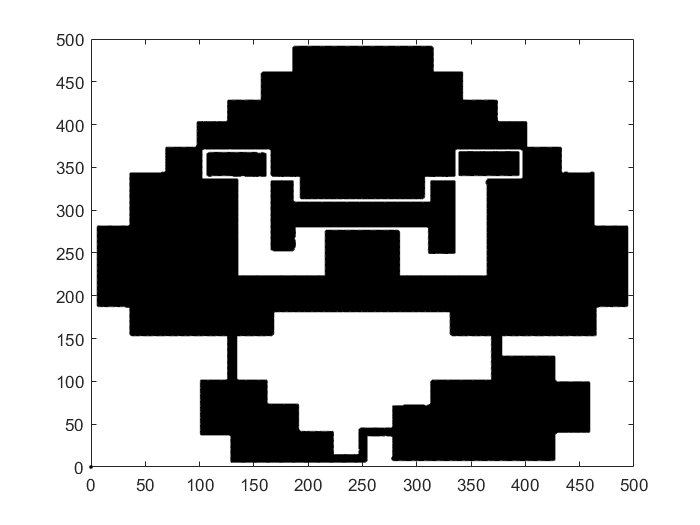

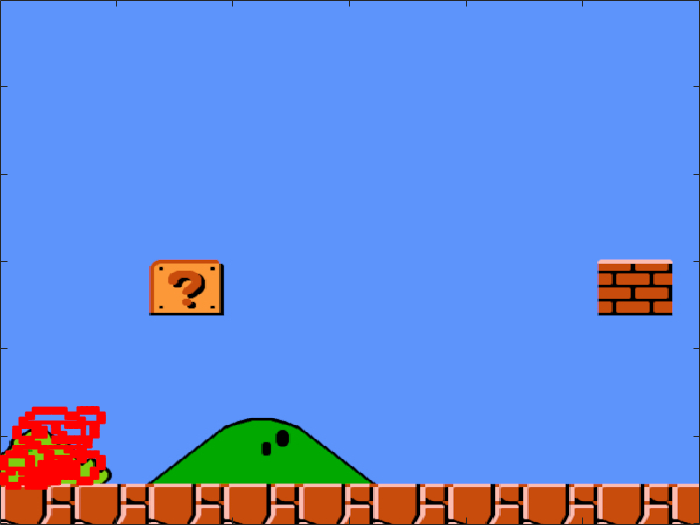


% images to 3x3 matrices
Jmario = imread('jumpingmario.jpg');
mushroom = imread('mushroom.jpg');
goomba = imread('goomba.jpg');
Jmario = Jpeg2pointsConverter(Jmario, 150);
mushroom = Jpeg2pointsConverter(mushroom, 200);
goomba = Jpeg2pointsConverter(goomba, 150);
Jmario(3,:) = ones(1, length(Jmario));
mushroom(3,:) = ones(1, length(mushroom));
goomba(3,:) = ones(1, length(goomba));

clf
% establishing background
ha = axes('units','normalized', 'position',[0 0 1 1]); 
uistack(ha,'bottom');
bg = imread('SunnyMarioLevelV2.jpg');
hi = imagesc(bg(400:1000,1:600, 1:3));
hb = axes('position',[0 0 1 1]);
hold on;
% scaling

mushroom = scale(mushroom, 1/8, 1/8);
origmushroom = mushroom;
Jmario = scale(Jmario, .3, .3);
origJmario = Jmario;
goomba = scale(goomba, .2, .2);
origgoomba = goomba;


axis([0 800 0 800]);
% Jmario = reflect(Jmario, 'y');
mushroom = translate(mushroom, 600, 50);
Jmario = translate(Jmario, 0, 60);



h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');
h_mushroom = scatter(hb, mushroom(1, :), mushroom(2, :), 'k.');

set(gca,'color','none','handlevisibility','off','visible','off');
% Mario standing still and further away mushroom. (2 Seconds)
% No transformations, Stand still frame  
% Standing Mario, Mushroom
for i = 1:2
    pause(1);
end


% Mario does a flip in and air and lands back down (3 seconds)
% Mario shifts and rotates
% Asset(s): Standing Mario, Jumping Mario, Mushroom
% R = [cos(pi/18) -sin(pi/18) 0; sin(pi/18) cos(pi/18) 0; 0 0 1];
for i = 1:12
     Jmario = translate(Jmario, 0, 30);
     delete(h_Jmario);
     h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');
     pause(.1)
end
for i = 1:12
     Jmario = translate(Jmario, 0, -30);
     delete(h_Jmario);
     h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');
     pause(.1)
end


% Mario stands in place and Mushroom shimmies offscreen (3 seconds)      
% Mushroom shifts offscreen (shifts)
% Asset(s): Standing Mario, Mushroom
% pause(1.5)
for i = 1:12
    mushroom = translate(mushroom, 50, 0);
    delete(h_mushroom);
    h_mushroom = scatter(hb, mushroom(1, :), mushroom(2, :), 'k.');
    pause(.1);
end


% Mario runs after mushroom and camera follows (3 seconds)
% Mario shifts right, and rotates clockwise and counterclockwise looks like a wobble
% Asset(s): Standing Mario, Jumping Mario, 
for i = 1:10
    Jmario = translate(Jmario, 35, 0);
    delete(h_Jmario);
    h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');
    pause(.1);
end


% Brown Goomba walks toward Mario, Mario stops goes backward, and jumps on it(5 seconds) 
% Goomba reflections and shifts, Mario shifts 
% Asset(s): Standing Mario, jumping Mario, Big footed Goomba

goomba = translate(goomba, 800, 60);
h_goomba = scatter(hb, goomba(1, :), goomba(2, :), 'k.');
for i = 1:10
    if i >2 && i<5
        Jmario = translate(Jmario, -40, 0);
        delete(h_Jmario);
        h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');   
    end
%     if i == 6
% %         Jmario = reflect(origJmario, 'y');
%         delete(h_Jmario);
%         h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');   
%     end 
    goomba = translate(goomba, -40, 0);
    delete(h_goomba);
    
%     goomba = reflect(goomba, 'y');
    h_goomba = scatter(hb, goomba(1, :), goomba(2, :), 'k.');   
    pause(.1);
end


% Jmario = translate(Jmario, 100, 0);

% R = [-1 0 0; 0 1 0; 0 0 1];
% Jmario = R*Jmario;
% Jmario = reflect(Jmario, 'y');
% delete(h_Jmario);

% delete(h_Jmario);
% axis([-1000, -1000, 1000 1000]);
% h_Jmario = scatter(hb, Jmario(1, :), Jmario(2, :), 'r.');
% for i= 1:5
%     
%     pause(.1);
% end

% Mario reaches big gap, stops in place, jumps up and down, then jumps over gap (5 seconds)
% Mario shifts
% Asset(s): Standing Mario, Jumping Mario

% Mario reaches the not moving mushroom, Mario transforms into a red goomba (3 seconds)
% Mario shifts and morphs(standing Mario-> Big footed Goomba)
% Asset(s): Standing Mario, Mushroom, Big footed Goomba
 
% Goomba Mario stops and wobbles in place, and proceeds toward the end of level (4 seconds)
% Goomba Mario Shears left and right (wobble), Reflections and shifts after
% Asset(s): Big footed Goomba

% Goomba Mario goes down pipe (2 seconds)
% Shears downward like a pankcake.
% Asset(s): Red Goomba
% end



% SCENE 2

% SCENE 3

% SCENE 4